# Worksheet 5, Part 4 / 4: Modeling Uncertain Quantities

*Author: *Zachary del Rosario, Summer 2023

*Important Note:* Worksheet 5 comes to you in **four**** parts**; `worksheet5_part1_assignment.mlx`, `worksheet5_part2_assignment.mlx`, and `worksheet5_part3_assignment.mlx`, and `worksheet5_part4_assignment.mlx`

*Learning Objectives:* As a result of working through this notebook, you will learn:

- How to select a distribution to model an uncertain quantity

- How to fit a distribution with a sample

- How to account for uncertainty in a deterministic model

- How to assess a fitted distribution using a QQ plot

- A bit about emergent properties of models

### Additional Files

Make sure to download these additional files from Canvas and place them in the same folder as this worksheet:

- `action_sir_v2.m`

- `simulate_sir_v2.m`

- `simulate_absir.m`

- `qqplot2.m`

## Overview

Over the past couple parts of the worksheet we have focused on replicating the specific modeling efforts of Althouse et al. (2020). In this fourth and final part of the worksheet, we'll zoom out from this specific modeling effort to talk about more generalizable lessons about going beyond single values by modeling uncertain quantities.

Althouse et al. (2020) made very detailed comparisons between the poisson and negative binomial distributions. But these are not the only distributions that exist! More importantly, these are not always the *right *choice of distribution for all circumstances. Let's talk about a few different distribution familities and their applications to modeling.

## List of Distributions

Distributions come in two broad categories: discrete and continuous.

### Discrete Distributions

Discrete random variables only allow for integer values.

#### Binomial Distribution

The binomial distribution is used to model a specific number of success occurring, given a probability of success `p` and a number of trials `N`. The binomial distribution assumes that all trials are independent; that no single outcome depends on any other outcome. For instance, the binomial distribution can model the probability of landing a heads in a single coin flip.

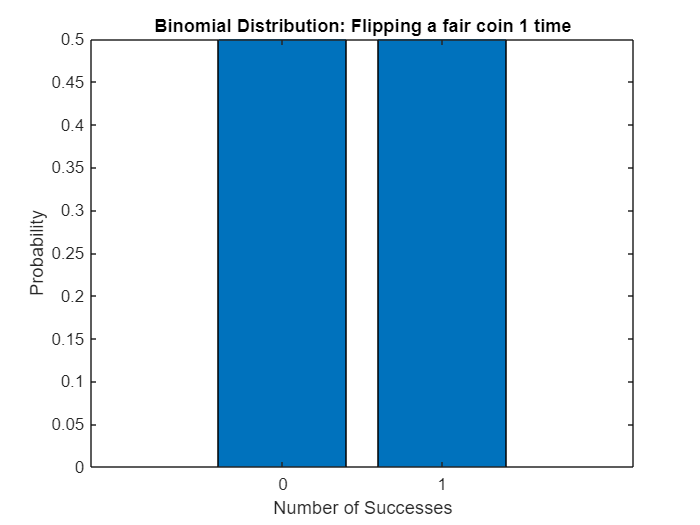

% Initialize distribution
p = 0.5; % Success probability (e.g., of landing a heads)
N = 1;   % Number of trials    (e.g., number of coin flips)
pd_binomial = makedist('Binomial', 'p', p, 'N', N);

% Visualize
x = 0:N;
pr = pd_binomial.pdf(x);
figure();
bar(x, pr)
xlabel('Number of Successes')
ylabel('Probability')
title('Binomial Distribution: Flipping a fair coin 1 time')

By adjusting the distribution parameters we can represent other cases, such as flipping a biased coin multiple times.

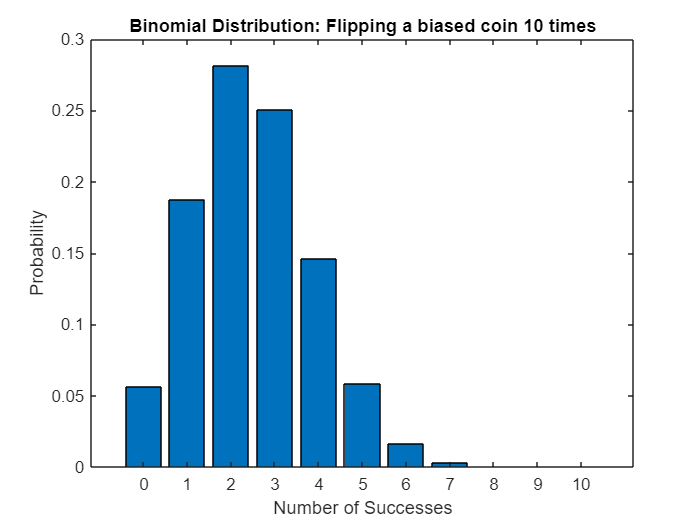

% Initialize distribution
p = 0.25; % Success probability (e.g., of landing a heads)
N = 10;   % Number of trials    (e.g., number of coin flips)
pd_binomial = makedist('Binomial', 'p', p, 'N', N);

% Visualize
x = 0:N;
pr = pd_binomial.pdf(x);
figure();
bar(x, pr)
xlabel('Number of Successes')
ylabel('Probability')
title('Binomial Distribution: Flipping a biased coin 10 times')

*Aside*: In probability and statistics, we call a single observation of a random variable a *trial* (or *realization*). This could be a single coin flip (for a binomial with `N=1)`, or a set of 10 coin flips (for a binomial with `N=10`).

The binomial distribution is not only used to model coin flips! We can use a binomial distribution to represent any scenario where the outcomes are binary (either success or failure), but there are multiple instances of this binary outcome. Some examples include:

- How many similarly-manufactured parts **from a batch of fixed-size** will have the correct tolerances?

- How many roughy-equivalent students **in a specific class** will pass an exam?

- How many roughly-equivalent patients **in a cohort** will contract a disease?

Note that the **bolded** sections of these examples imply a fixed number of trials. If we don't have a fixed number of trials, we need to model the scenario with a different distribution.

#### Exercise 1 / 11

Modify the provided code to help answer the questions below.

% TODO: Edit this code to answer the questions below
p = 0.1; % Success probability
N = 5;   % Number of trials

% NOTE: Do not edit this code
% Initialize distribution
pd_binomial = makedist('Binomial', 'p', p, 'N', N);
sd_binomial = std(pd_binomial)

sd_binomial = 0.6708

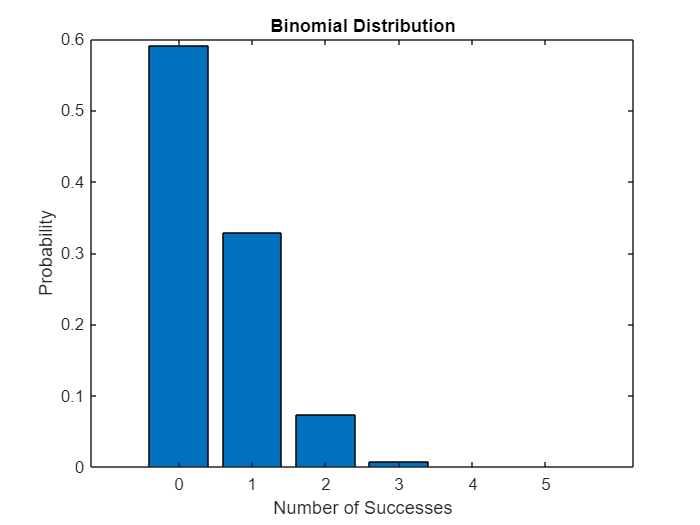


% Visualize
x = 0:N;
pr = pd_binomial.pdf(x);
figure();
bar(x, pr)
xlabel('Number of Successes')
ylabel('Probability')
title('Binomial Distribution')

- What does increasing the number of trials tend to do to the variability (standard deviation, sd) of the binomial distribution?

- *    (Write your response here.) *It lessens it and concentrates all the successes in the middle.

- What does changing the success probability to extreme (`p=0.1` or `p=0.9`) tend to do to the shape of the distribution?

- *    (Write your response here.) *Raising it moves the distribution to the right while lessening it moves it to the left.

#### Poisson Distribution

The poisson distribution is used to model the number of success in a given period of time, given an average number of successes in that time period `lambda`. The poisson distribution assumes that all successes are independent, and the underlying population is very large—effectively infinite. For instance, the poisson distribution can be used to model the number of cases of the flu that occur within a large city over a month.

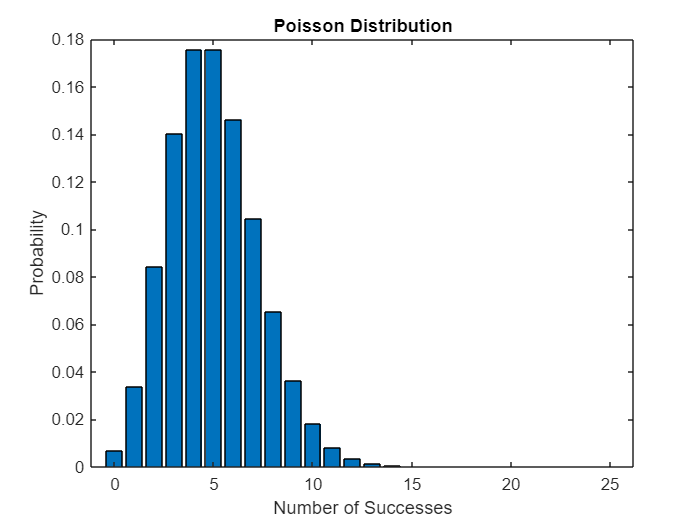

% Initialize distribution
lambda = 5; % Average number of events in the period (e.g., flu cases in a month)
pd_poisson = makedist('Poisson', 'lambda', lambda);

% Visualize
x = 0:lambda*5;
pr = pd_poisson.pdf(x);
figure();
bar(x, pr)
xlabel('Number of Successes')
ylabel('Probability')
title('Poisson Distribution')

In contrast with the binomial distribution, the poisson distribution does not specify a number of trials. Instead, we only specify the average number of successes in the time period of interest. The difference between using a poisson distribution vs a binomial distribution will depend on the scenario we seek to model. For instance, the following variations on the previous examples would warrant a poisson model (rather than binomial):

- How many similarly-manufactured parts **over a month of production** will have the correct tolerances? 

- How many roughy-equivalent students **over 4 years** will pass an exam?

- How many roughly-equivalent patients **over 6 months** will contract a disease?

Note that the **bolded** sections of these examples imply no known number of trials, but rather a fixed time period of interest.

*Aside*: In probability and statistics, we describe the outcome of interest as a "success," even if that outcome is something negative. While it's not a social "success" for someone to contract a disease, it is a probabilistic "success" for someone to contract a disease if that's the outcome we're trying to study.

#### Negative Binomial Distribution

Note that the poisson distribution takes just one parameter; this makes it less flexible than other distributions. As we saw in previous parts of the worksheet, the negative binomial distribution takes two parameters, which increases its flexibility. In particular, it adds a dispersion parameter `k` that controls the variability of the distribution. Unlike the poisson distribution, the negative binomial distribution *does not* assume independence of successes; in fact, the dispersion parameter controls how related successes are.

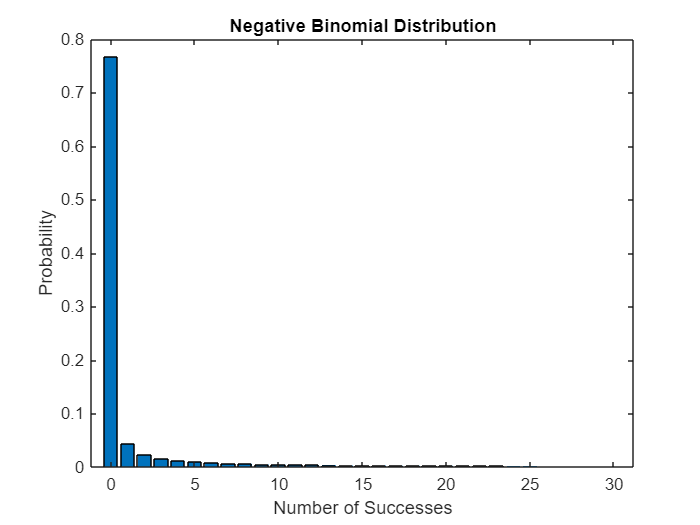

% Initialize distribution
k = 0.057; % Dispersion parameter
m = 6;   % Average number of events in the period (e.g., flu cases in a month)
% Convert to MATLAB parameterization
p = 1 / (1 + m / k);
pd_nb = makedist('NegativeBinomial', 'r', k, 'p', p);

% Visualize
x = 0:m*5;
pr = pd_nb.pdf(x);
figure();
bar(x, pr)
xlabel('Number of Successes')
ylabel('Probability')
title('Negative Binomial Distribution')

As we saw in the previous parts of the worksheet, Althouse et al. (2020) showed that a negative binomial distribution is a much better model for secondary covid-19 cases than the poisson distribution. This is because covid-19 transmission is *overdispersed*; the vast majority of index cases lead to zero additional cases, but rare super-spreading events (SSEs) can lead to extreme numbers of secondary cases. SSEs are an extreme form of dependency (non-independence) between successes; a SSE is, by definition, an event where many infections tend to occur at the same time.

### Exercise 2 / 11

Modify the provided code to help answer the questions below. This plot includes a "control" distribution with dispersion parameter `k=0.2` and mean `m=5`.

% TODO: Edit this code to answer the questions below
k = 0.1; % Dispersion parameter
m = 100;   % Mean

% NOTE: Do not edit this code
% Initialize distribution
% Convert to MATLAB parameterization
p = 1 / (1 + m / k);
pd_nb_new = makedist('NegativeBinomial', 'r', k, 'p', p);
sd_nb = std(pd_nb_new)

% Visualize
x = 0:pd_nb.icdf(1 - 1e-3); % Note the use of the ICDF
pr = pd_nb.pdf(x);

sd_nb = 316.3858

pr_new = pd_nb_new.pdf(x);
figure();
semilogy(x, pr, '.--', 'DisplayName', 'Control'); hold on
semilogy(x, pr_new, '.--', 'DisplayName', 'Modified')
xlabel('Number of Successes')
ylabel('Probability')
title('Negative Binomial Distribution')
legend()

*Note:* The code above uses the inverse cumulative distribution function (ICDF) to compute the number of successes associated with the probability 1 - 0.001. I use this to adjust the x-scale of the plot. Formally, the ICDF tells us a value ICDF(p) such that there is probability `p` that the random variable is less than that value X < ICDF(p). This is a way to help quantify extreme events, either using `p` small (e.g., 1e-3) or `p` large (e.g., 1 - 1e-3).

- What does increasing the dispersion parameter tend do to the variability (standard deviation, sd) of the negative binomial distribution?

- *    (Write your response here.) *It increases the variability.

- What does increasing the dispersion parameter tend do to the probability of extreme events (large numbers of successes)?

- *    (Write your response here.) *It decreases the probability of extreme events.

- What does increasing the mean tend to do to the variability?

- *    (Write your response here.) *It decreases it.

- What does increasing the mean tend to do to the probability of extreme events?

- *    (Write your response here.) *It increases it.

### Exercise 3 / 11

Consider the following scenario:

> Every academic year in the Fall, when students return to Olin, we tend to see an initial round of illness (colds and the like). Over the past few years, we've seen that about 20 out of 350 students tend to get sick each Fall. The ModSim teaching team is trying to determine how many of their 100 students might get sick in the first few weeks of class.

Define a distribution model for **the number of sick students in ModSim,** and answer the questions below.

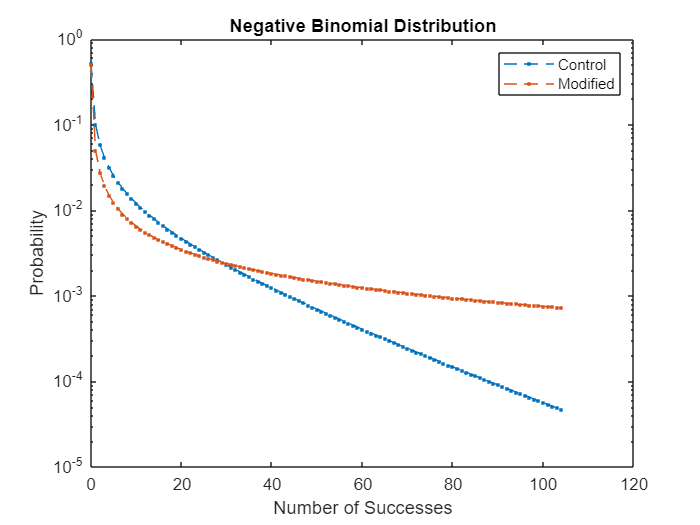

% TODO: Use a distribution to answer the questions below
k = 0.057; % Dispersion parameter
m = 6;   % Mean
p = 1 / (1 + m / k);

pd_model =  makedist('NegativeBinomial', 'r', k, 'p', p);
% NOTE: Do not edit this code, use this to help answer the questions below
% Assertions
assert(pd_model.cdf(-1e-3) == 0, 'Your distribution puts nonzero probability on negative values, which is unrealistic.')
assert(pd_model.pdf(101) <= eps(1), 'Your distribution puts nonzero probability on over 100 sick students, which is impossible.')
assert(mean(pd_model) > 5, 'Your mean number of sick students is much too small to be realistic.')
assert(~isequal(class(pd_model), 'prob.PoissonDistribution'), 'The poisson distribution assumes an infinitely large population, but we only have 100 students.')
disp('Assertions passed')

% Visualize
x = 0:100;
pr = pd_model.pdf(x);
figure();
bar(x, pr)
xlabel('Number of Sick Students')
ylabel('Probability')
title('Your Distribution Model')

- What distribution did you use to model this scenario? Why is this a reasonable model?

- *    (Write your response here.) *A negative binomial distribution due to it the poisson distribution assuming an infinitely large population.

- What is a reasonable number of sick students for the ModSim teaching team to expect? How did you pick that number?

- *    (Write your response here.) *0 since it is the number with the highest probability.

### Continuous Distributions

Continuous random variables allow for real valued outcomes—not just integers.

#### Normal Distribution

The normal distribution is a well-known distribution. It is fully-defined by its mean `mu` and standard deviation `sigma`, and has a familiar "bell-shaped curve."

% Initialize distribution
mu = 5;    % Average

Assertions passed


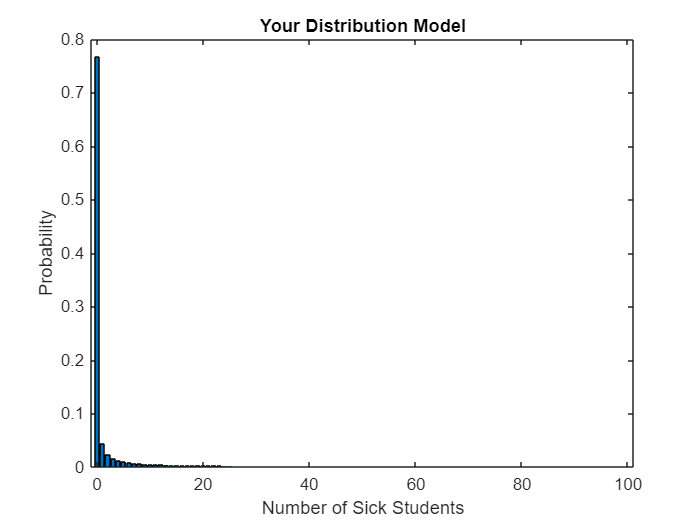

sigma = 1; % Standard deviation
pd_normal = makedist('Normal', 'mu', mu, 'sigma', sigma);

% Visualize
x = linspace(mu - 3*sigma, mu + 3*sigma, 200);
pr = pd_normal.pdf(x);
figure();
plot(x, pr)
xlabel('Value')

ylabel('Probability Density')
title('Normal Distribution')

While the normal distribution is a common distribution, it is **not** the only distribution for continuous quantities. People often use the normal distribution as a "default" distribution, or assume that it is the "true" shape of randomness—this is [incredibly foolish](https://psycnet.apa.org/doiLanding?doi=10.1037%2F0033-2909.105.1.156).

In particular, the normal distribution allows for values from $-\infty$ to $+\infty$; if you need a distribution that has strict bounds on its values, then you should use a different distribution model, such as...

#### Beta Distribution

The beta distribution takes values between [0, 1], but has a great deal of flexibility in its shape.

% Initialize distribution
a = 2; % First shape parameter
b = 2; % Second shape parameter
pd_beta = makedist('Beta', 'a', a, 'b', b);

% Visualize
x = linspace(0, 1, 200);
pr = pd_beta.pdf(x);
figure();
plot(x, pr)
xlabel('Value')
ylabel('Probability Density')
title('Beta Distribution: a=2, b=2')

Setting a < 1 tends to concentrate the distribution towards 0, while setting b < 1 tends to concentrate the distribution towards 1. Setting a = b = 1 gives a flat distribution (a special case called the uniform distribution). Note that the flat distribution gives no preference to any values in the interval $[0, 1]$; in that sense, it is *maximally uncertain* about the uncertain quantity.

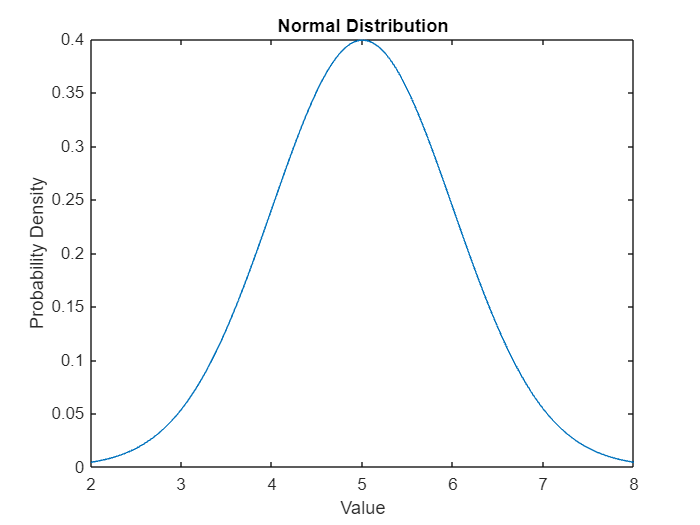

% Initialize distributions
pd_beta_a05_b01 = makedist('Beta', 'a', 0.5, 'b', 0.1);
pd_beta_a01_b05 = makedist('Beta', 'a', 0.1, 'b', 0.5);
pd_beta_a10_b10 = makedist('Beta', 'a', 1.0, 'b', 1.0);


% Visualize
x = linspace(0, 1, 200);
figure();
plot(x, pd_beta_a05_b01.pdf(x), 'DisplayName', 'a=0.5, b=0.1'); hold on
plot(x, pd_beta_a01_b05.pdf(x), 'DisplayName', 'a=0.1, b=0.5')
plot(x, pd_beta_a10_b10.pdf(x), 'DisplayName', 'a=1.0, b=1.0')
xlabel('Value')
ylabel('Probability Density')
title('Beta Distributions')
legend()

Setting a > 1 tends to shift the distribution *away* from 0, while setting b > 1 tends to shift the distribution *away* from 1.

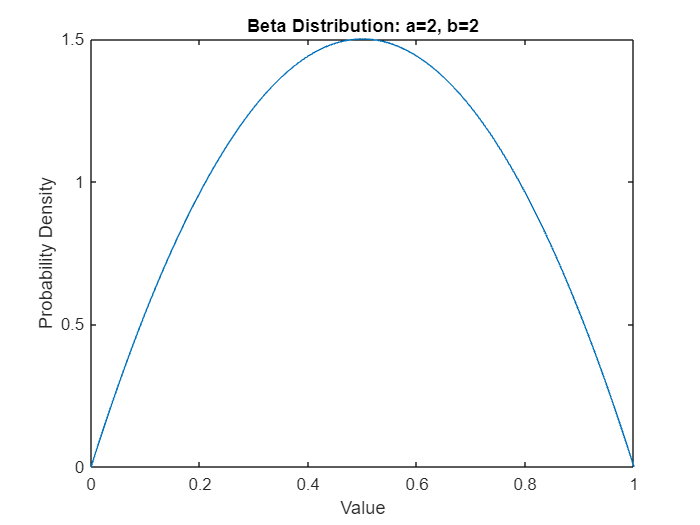

% Initialize distributions
pd_beta_a30_b10 = makedist('Beta', 'a', 3.0, 'b', 1.0);
pd_beta_a10_b30 = makedist('Beta', 'a', 1.0, 'b', 3.0);
pd_beta_a10_b10 = makedist('Beta', 'a', 1.0, 'b', 1.0);

% Visualize
x = linspace(0, 1, 200);
figure();

plot(x, pd_beta_a30_b10.pdf(x), 'DisplayName', 'a=3.0, b=1.0'); hold on
plot(x, pd_beta_a10_b30.pdf(x), 'DisplayName', 'a=1.0, b=3.0')
plot(x, pd_beta_a10_b10.pdf(x), 'DisplayName', 'a=1.0, b=1.0')
xlabel('Value')
ylabel('Probability Density')
title('Beta Distributions')
legend()

If you need the beta distribution to represent values between a different range, say $[l, u]$, you can use a simple transformation. Let $B \sim \textrm{Beta}(a, b)$ be a beta distribution with shape parameters $a, b$. Then we can construct a beta distribution $X$ between $[l, u]$ using the transformation


$$X=\left(u-l\right)B+l\ldotp$$


### Exercise 4 / 11

Consider the following scenario:

> We are fitting a compartmental SIR model, and are conducting literature research to determine appropriate values. In a relevant article, we find the authors have estimated that the infectivity parameter $\beta$ likely lies between $[0.1, 0.9]$ for our scenario of interest. They provide no additional information, so we should treat $\beta$ as maximally uncertain but strictly within the stated interval.

Define a distribution model for **the infectivity parameter **$\beta$**,** and answer the questions below.

*Hint*: You will have to *transform* your distribution to adequately solve this problem. There is space in the code for you to transform your data.

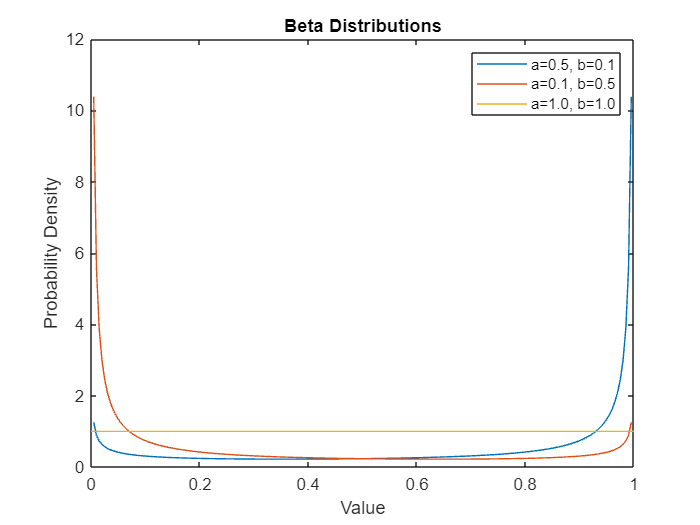

% TODO: Use a distribution to answer the questions below
pd_base = makedist('Beta', 'a', 1.0, 'b', 1.0); % Define your distribution model

% NOTE: Do not edit this code, transform these realizations
B = random(pd_base, 1, 500);

% TODO: Transform the sample based on the scenario above
X = (0.9-0.1)*B+0.1; % Complete this transformation

%% NOTE: Do not edit this code, use this to help answer the questions below

% Assertions
assert(min(X) >= 0.1, 'Your transformed distribution is too wide')
assert(max(X) <= 0.9, 'Your transformed distribution is too wide')
assert(min(X) <= 0.15, 'Your transformed distribution is too narrow')
assert(max(X) >= 0.85, 'Your transformed distribution is too narrow')
disp('Assertions passed')

% Visualize
figure();
histogram(X)
xlabel('Infectivity Parameter')
ylabel('Count')
title('Your Distribution Model: Sample')

- What distribution did you use to model this scenario? Why is this a reasonable model?

- *    (Write your response here.) *The beta distribution because it allowed me to treat every beta value as maximally uncertain.

## Propagating Uncertainty Through A Deterministic Model

The previous exercise raises an important scenario: What do we do when we have a deterministic model, but some of our parameter values are uncertain? In this setting we can run the deterministic model *repeatedly* with different values of the uncertain parameters. This will allow us to *propagate* the uncertainty through the model so we can see how different parameter values lead to different potential outcomes. 

You'll learn more about uncertainty propagation in the next few exercises.

### Exercise 5 / 11

Complete the code below to run the compartmental SIR model at each of the infectivity parameter values $\beta$ that you generated in the previous exercise.

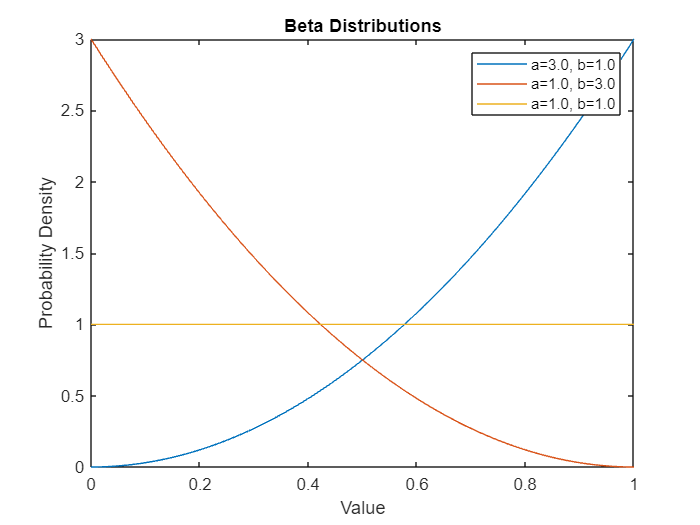

% NOTE: Do not edit this code
% Use the following parameter values
s_1 = 99;
i_1 = 1;

r_1 = 0;
gamma = 0.3;
T_end = 30;
count = 1;
beta = 0.1;
% Store the infection results in this array
I_all = zeros(9, T_end);

% TODO: Write a for loop to iterate over all realizations of the beta parameter
for i = 1:9
    [S, I, R, W] = simulate_sir_v2(s_1, i_1, r_1, beta, gamma, T_end);
    beta = beta + 0.1;
    I_all(count,:) = I;
    count = count + 1;
end
% NOTE: Do not edit this code, use this to check your work
% Check assertions
assert(min(max(I_all, [], 2)) > 50, 'One of your infection peaks is too small; did you use the transformed sample?')
disp('Assertions passed')

% Plot all results
figure()
plot(W, I_all, 'k')

### Exercise 6 / 11

Complete the code below to extract the infection peaks from the ensemble you generated in the previous exercise. Answer the questions below.

% TODO: Compute the infection peak for each realization in I_all
I_comp_peaks = max(I_all,[],2);


Assertions passed


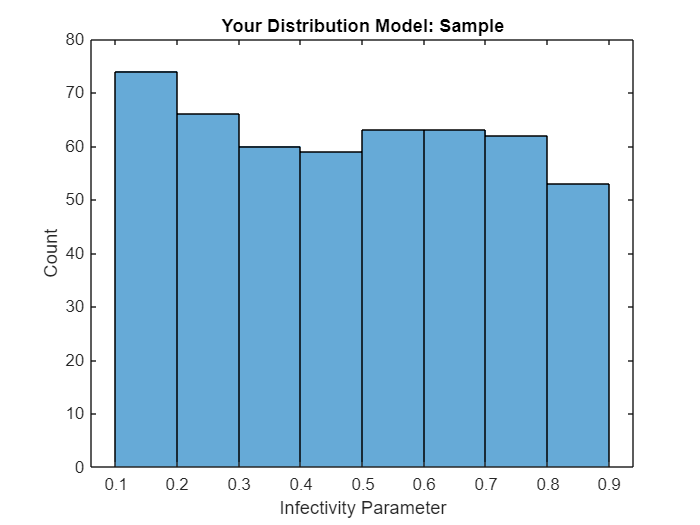

% NOTE: Do not edit this code, use this to check your work
% Check assertions
assert(min(I_comp_peaks) >= 50, 'One of your infection peaks is too small; did you take the max over the correct axis?')

% Visualize
figure()
histogram(I_comp_peaks)

xlabel('Infection Peak')
ylabel('Count')
title('Possible Infection Peaks: Compartmental Model')

- Describe the shape of the distribution of infection peak values. Is it the same shape as the distribution you defined for the infectivity parameter $\beta$?

- *    (Write your response here.) *The middle peak is the largest with the leftmost peak being the smallest and the rightmost peak being the greatest. This is not that similar to my distribution for the infectivity parameter.

- What is the most likely number for the infection peak?

- *    (Write your response here.) *Anywhere inbetween 80 and 90, most likely 85.

- What is the smallest the infection peak could be?

- *    (Write your response here.) *70

## Quantile-Quantile (QQ) Plots

In the previous exercise you described the shape of a distribution by inspecting a histogram. While this is a useful first step, a much more powerful tool is to construct a *quantile-quantile (QQ) plot*. A QQ plot visualizes a sample against quantiles from a reference distribution. **A high-quality fit should appear as a straight line on a QQ plot.** 

For instance, the following code draws a sample from a normal distribution, then constructs a QQ plot against the same normal distribution.

% Create the distribution
pd_norm = makedist('Normal');
% Draw a sample
X_norm = random(pd_norm, 1, 1000);

% Create a QQ plot
figure();
qqplot2(X_norm, pd_norm)

The case above is a "perfect" example—the theoretical distribution exactly matches the population underlying the data. As can be seen above, even in this "perfect" case, the points do not land exactly on the diagonal line. In particular, we see the points at the extreme lower and upper ends of the line depart **a little** from the line. More extreme departures from this diagonal line indicate a poor fit in that region of the distribution.

You will practice interpreting a QQ plot in the next exercise.

### Exercise 7 / 11

Run the following code, inspect the QQ plot, and answer the questions below.

% NOTE: Do not edit this code; use this to answer the questions below
% Fit a normal distribution to the infection peak data
pd_comp_peak = fitdist(I_comp_peaks, 'Normal');
% Visualize with a QQ plot
figure();
qqplot2(I_comp_peaks, pd_comp_peak)
title('Normal Fit to Infection Peak Data: Compartmental Model')

infected = 89.1000

infected = 79.2000

infected = 69.3000

infected = 59.4000

infected = 49.5000

infected = 39.6000

infected = 29.7000

infected = 19.8000

infected = 9.9000

- What regions of the QQ plot indicate **close agreement** between the theoretical and observed quantiles?

- *    (Write your response here.) *The middle and right most regions.

- What regions of the QQ plot indicate **poor agreement** between the theoretical and observed quantiles?

- *    (Write your response here.) *The leftmost regions.

- Could you use the fitted normal distribution to make accurate predictions about **extreme values** (small or large) using this distribution?

- *    (Write your response here.) *

- Is this distribution normal? Why or why not?

- *    (Write your response here.) *No, because there is a great amount of variation between where the points lie and the line.

*Aside:* You can fit other distributions to data! Using the `fitdist()` tool, you just need to change the distribution argument. In this way, you can test other distribution fits to a dataset.

## Emergent Properties in a Model

The examples above illustrate an important point: Models can have very non-simple behavior in their results. These results tend to be more complex than the simple tools (e.g., distributions, simple curves) than we use to construct those models. In other words, models often have complex *emergent* properties.

As one final example, let's revisit the agent-based SIR model. The following code sets up the model assuming homogeneous social connectivity, and generates an ensemble of infection curves.

% NOTE: Do not edit these parameters, or the code below
% Set up parameter values
infection_rate = 0.005; recovery_rate = 0.05;
n_population = 100;

Assertions passed


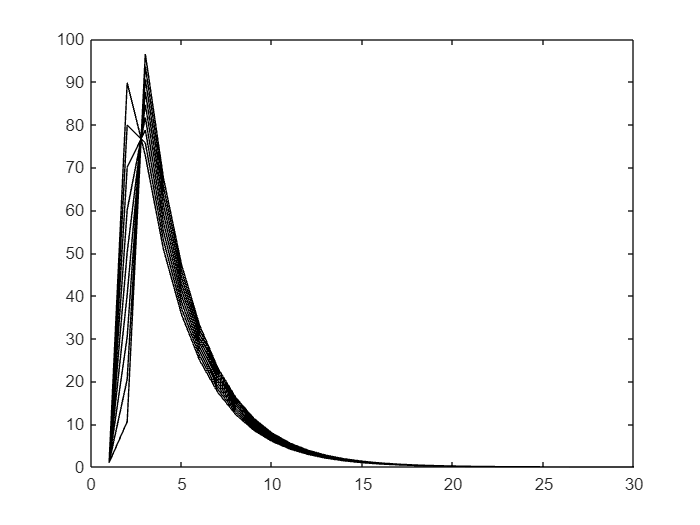

M_compartmental = ones(n_population, n_population) - eye(n_population);
% One initial infected person
Iv1 = zeros(n_population, 1); Iv1(1) = 1;


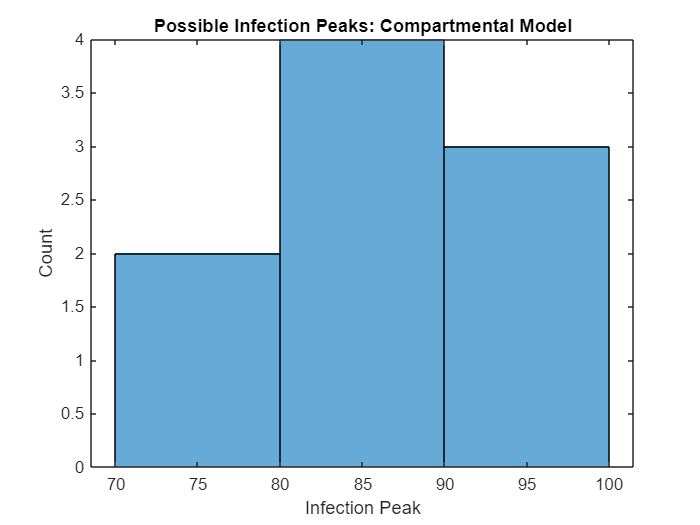

% Set up simulation parameters
n_realizations = 501;
T_simulation = 150;
% Reserve space for simulation results
I_ensemble = zeros(T_simulation, n_realizations);
% Generate the sample of results
rng(101)
for i = 1 : n_realizations
    % Run a single simulation
    [Sh, Ih, Rh] = simulate_absir(...
        M_compartmental, ...
        Iv1, ...
        T_simulation, ...
        infection_rate, ...
        recovery_rate ...
    );
    % Summarize and store the infection history

    I_ensemble(:, i) = sum(Ih, 1);
end

% Visualize the results
figure();
plot(I_ensemble, 'k')
xlabel('Timestep')
ylabel('Infected Persons')
title('Ensemble of Agent-Based SIR Simulations')

First, let's think critically about the uncertainty in the agent-based SIR model. How does this compare with the branching process models we studied in the previous parts of the worksheet?

### Exercise 8 / 11

Inspect the code above, including the source code for `simulate_absir()`. Answer the questions below.

- Where does the uncertainty in the agent-based SIR model come from? What does this uncertainty represent? *Hint:* Look for where the "random values" are generated.

- *    (Write your response here.) *The randomness comes from the infection and recovery rates.

- Where does the uncertainty in the branching process model come from? Does this uncertainty pertain to individual persons, or a set of persons?

- *    (Write your response here.) *It partains to individual persons and has to do with the random nature of transmission.

- Look at the code above, including the source code. Is there anywhere we can "plug in" a negative binomial distribution to represent an overdispersed disease? *Hint:* Keep in mind what we've used a negative binomial distribution to represent; does it represent the outcomes for a single person? Or for a set of persons?

- *    (Write your response here.) *Instead of a random number we could use a negative binomial distribution.

### Exercise 9 / 11

Complete the code below to extract the infection peaks from the agent-based ensemble generated above. Answer the questions below.

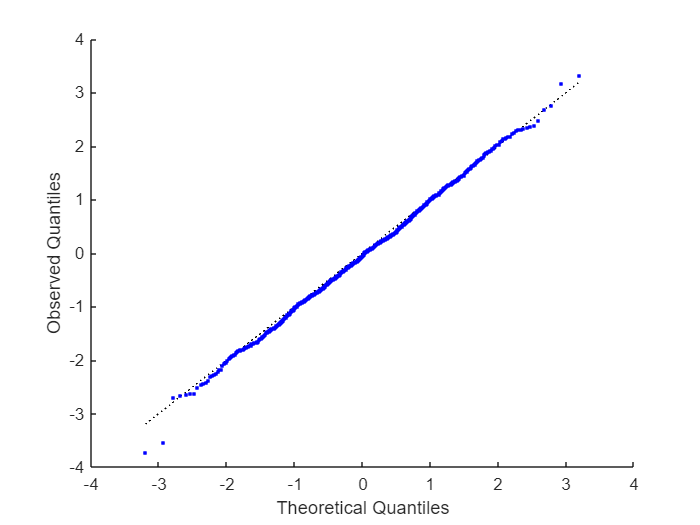

% TODO: Create a histogram of the infection peak values in I_ensemble
% Make sure your data are in the form of a *column vector*
I_ab_peaks = max(I_ensemble, [], 1);
I_ab_peaks = I_ab_peaks';

% NOTE: No need to edit this code
% Check assertions
assert(length(I_ab_peaks) == n_realizations, 'Your set of peaks is not the right size. Did you use the right ensemble?')
assert(size(I_ab_peaks, 1) == n_realizations, "Your set of peaks must be a column vector. Use ' to transpose your data.")
disp('Assertions passed')

% Visualize
figure();
histogram(I_ab_peaks, 'NumBins', 50)
xlabel('Infection Peak')
ylabel('Count')
title('Possible Infection Peaks: Agent-Based Model')

- Describe the shape of this distribution. Does it have distinct "regions"? What is the shape of those "regions"?

- *    (Write your response here.) *There is one region that somewhat resembles a bell curve while the other is just one peak.

- What is **physically** happening that can account for the regions you identified above?

- *    (Write your response here.) *

- Can a normal distribution accurately describe the **entire** dataset shown here? Why or why not?

- *    (Write your response here.) *No, because there is the outlier all the way to the left.

- Could a normal distribution accurately describe a **subset** of the data shown here? Why or why not?

- *    (Write your response here.) *Yes because the right region resembles a bell curve.

### Exercise 10 / 11

Write your own code to fit a distribution to the agent-based infection peak data, and use a QQ plot to assess your fitted distribution. Answer the questions below.

*Hint*: You may find it helpful to *filter *the dataset to a subset, based on the observations you made above.

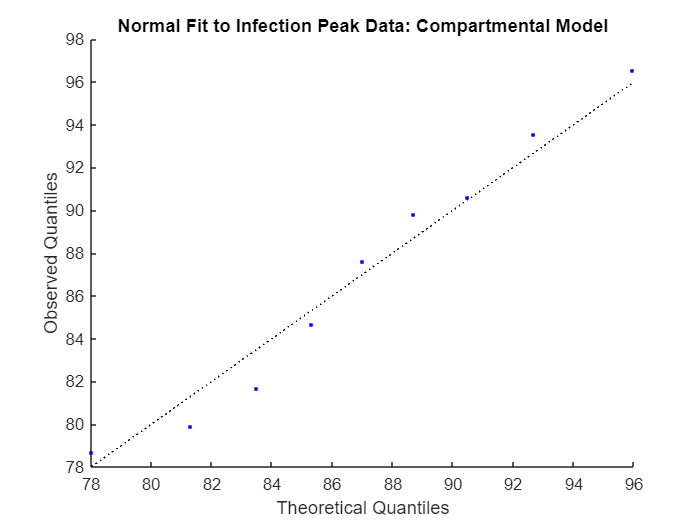

% TODO: Fit a distribution to the I_ab_peaks data,

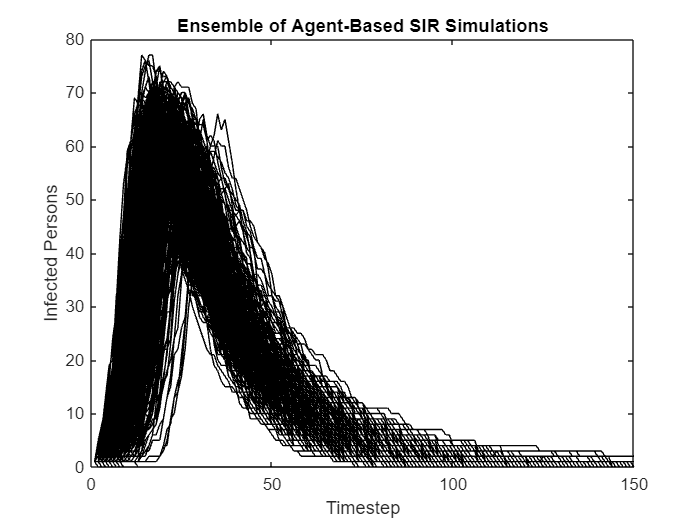

Assertions passed


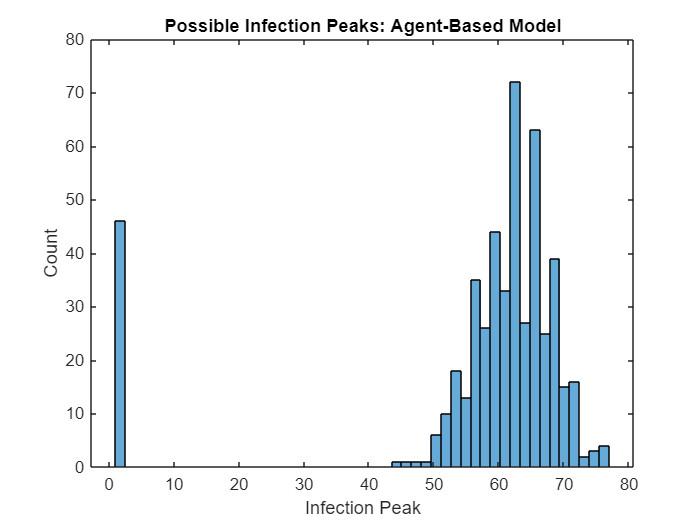

% create a QQ plot to assess your fit

- Is our data `I_ab_peaks` here continuous or discrete?

- *    (Write your response here.)*

- Did you fit a distribution to the entire dataset, or a subset? Why?

- *    (Write your response here.)*

- Which distribution did you choose? Was it continuous or discrete? Why did you choose that distribution?

- *    (Write your response here.)*

- Are there any limitations to the distribution you chose? How do those appear in the QQ plot?

- *    (Write your response here.)*

## Exercise 11 / 11 - Fix It!

Chose a part (<=1 paragraph) of your Project 2 Report that you would have liked to spend more time on, or you think that your writing did not fully represent your intended communication. Paste this section below, and then revise it. Consider the Clear and Concise and ABT frameworks we have been using throughout the course.

(Paste your original writing here)

Our first model shows these 7 pods with 20 nodes in each, this represents 7 classrooms with 20 students in

each of them. All the nodes in each pod are connected to each other modeling how every kid in the classroom

will interact in one way or another with every one of their classmates. We assume each connection between

the nodes is the same. We also assume the classrooms do not interact with one another. This is acceptable

for our modeling question because we are assuming there is so little contact between the other classes that

any contact that does happen is negligible. This model visually shows if we used the one classroom method to

decrease the spread of a disease, that disease would only be contained within that classroom and not spread to

the others

(Make your edits here)

Our first model shows 7 pods with 20 nodes in each pod, representing 7 classrooms with 20 students in each. Every child in the classroom interacts an equal amount with their peers in the classroom, represented through equal connections among each node. Every node is connected to every other node in a classroom by the same weight. We assume that the classrooms do not interact with each other in this model. This is an acceptable assumption because we are basing this idea off the social distancing seen during the covid-19 pandemic in schools, where people tried to distance themselves from others who they did not live with as much as possible. This is an ideal version of that senario, with the "houses" being the classrooms and the "families" being the 20 students in each house. Visually, this model shows that the one classroom method is successful in decreasing the spread of a disease, as the disease remains contained in a classroom, not spreading to the others.

## Towards the project!

Worksheet 5 has been all about going beyond a "single value." You've learned about random variables: when you should use them to model quantities, how to use distributions to represent different kinds of randomness, and how to use models with randomness to answer scientific questions. You'll use all of these lessons in Project 3.